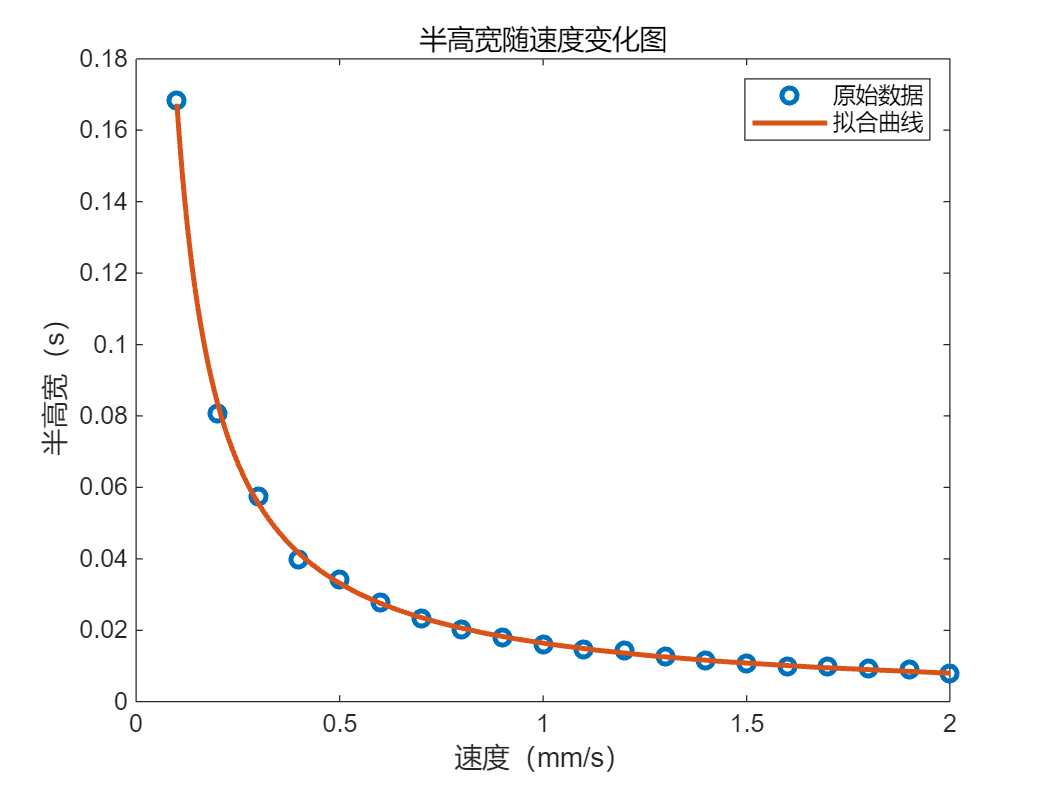

clear;clc;

% 定义数据

% x = [0.09818 0.20483 0.28784 0.41625 0.48174 0.59387 0.71265 0.81365 0.92676 1.0282 1.13243 1.1578 1.31636 1.43519 1.53657 1.65998 1.694 1.76639 1.84525 2.06668];
x = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0 1.1 1.2 1.3 1.4 1.5 1.6 1.7 1.8 1.9 2.0];
half_height_width = [0.1684 0.08072 0.05744 0.03972 0.03432 0.02784 0.0232 0.02032 0.01784 0.01608 0.0146 0.01428 0.01256 0.01152 0.01076 0.00996 0.00976 0.00936 0.00896 0.008];

% x = [0.1 0.2 0.3 0.4 0.6 0.7 0.8  1.6 2.0];
% half_height_width = [0.3227 0.24276 0.1725 0.13639 0.098907 0.091741 0.079551  0.053703 0.047152];

% 微流控实验，拍摄样本是血液，筛选并提取单一像素点的数据用于精确标定，找到速度与半高宽的对应关系 
% x = [0.5556 0.6944 0.8333 1.1111 1.3888 1.6667 1.9444];
% half_height_width = [0.023100 0.016800 0.014300 0.010100 0.009800 0.006800 0.005700];

% 微流控实验，拍摄样本是离心提纯后的血液，不筛选数据，提取一整行像素点的数据进行计算，最后取平均值 
% x = [0.2778 0.5556 0.8333 1.1111 1.3888 1.9444 2.2222];
% half_height_width = 4*[0.037767 0.031493 0.029609 0.028144 0.027999 0.02709 0.026862];

% 微流控实验，拍摄样本是离心提纯后的血液，在上面覆盖一层固态仿体（厚度0.8~1.0mm），不筛选数据，提取一整行像素点的数据进行计算，最后取平均值
% x = [0.2778 0.5556 0.8333 1.1111 1.3888 1.6667 1.9444 2.2222];
% half_height_width = [0.040783 0.035378 0.036155 0.034237 0.033006 0.033507 0.033334 0.032875];

% 微流控实验，拍摄样本是离心提纯后的血液，在上面覆盖一层固态仿体（厚度0.8~1.0mm），筛选并提取单一像素点的数据
% x = [0.2778 0.5556 0.8333 1.1111 1.3888 1.6667 1.9444 2.2222];
% half_height_width = [0.0638 0.0307 0.01944 0.01512 0.01196 0.00976 0.00848 0.00808];

% x = [0.5556 0.6944 0.8333 1.1111 1.3888 1.6667 1.9444];
% half_height_width = [0.092977 0.080046 0.0758 0.07865 0.076935 0.070986 0.07734];

% 对 x 取倒数
inv_x = 1 ./ x;

% 进行线性拟合
p = polyfit(inv_x, half_height_width, 1); % 一次多项式拟合倒数后的数据

% 计算拟合曲线的数据
inv_x_fit = linspace(min(inv_x), max(inv_x), 100);
y_fit = polyval(p, inv_x_fit);

% 绘制原始数据和拟合曲线
figure;
plot(x, half_height_width,'o', 'LineWidth', 2); % 原始数据，线宽设置为2
hold on;
plot(1 ./ inv_x_fit, y_fit, '-', 'LineWidth', 2); % 拟合曲线，线宽设置为2
hold off;

% 添加标题、图例和标签
title('半高宽随速度变化图'); % 添加标题
legend('原始数据', '拟合曲线');
xlabel('速度（mm/s）');
ylabel('半高宽（s）');


y_pred = polyval(p, inv_x);
SS_res = sum((half_height_width - y_pred).^2);
SS_tot = sum((half_height_width - mean(half_height_width)).^2);
R_squared = 1 - (SS_res / SS_tot);
disp(['R-squared: ', num2str(R_squared)]);

R-squared: 0.9993



RMSE = sqrt(mean((half_height_width - y_pred).^2));
disp(['RMSE: ', num2str(RMSE)]);

RMSE: 0.00096742



MAE = mean(abs(half_height_width - y_pred));
disp(['MAE: ', num2str(MAE)]);

MAE: 0.00063818
